     1



ans =     0.9995   -0.0316         0         0
    0.0316    0.9995         0         0
         0         0    1.0000         0
    0.0484    1.1003         0    1.0000


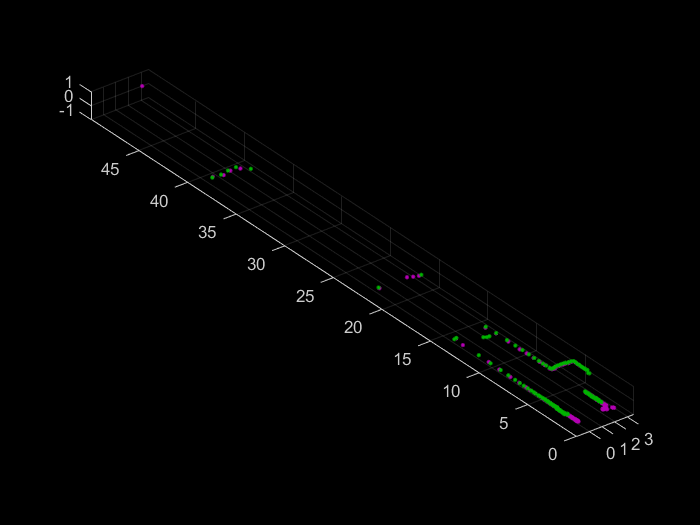

     2



ans =     0.9950   -0.1004         0         0
    0.1004    0.9950         0         0
         0         0    1.0000         0
    0.1943    2.2000         0    1.0000


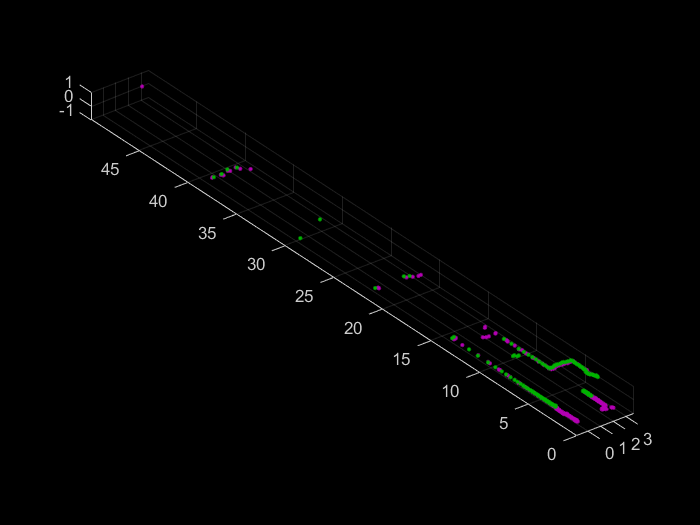

     3



ans =     0.9886   -0.1503         0         0
    0.1503    0.9886         0         0
         0         0    1.0000         0
    0.3392    3.3048         0    1.0000


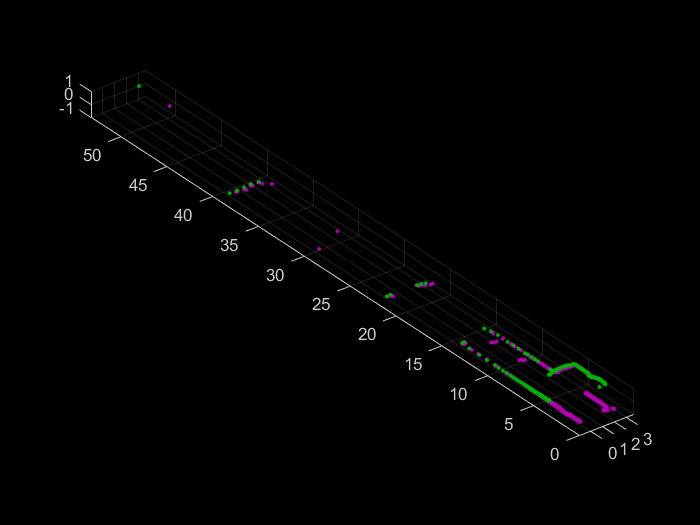

     4



ans =     0.9997   -0.0253         0         0
    0.0253    0.9997         0         0
         0         0    1.0000         0
    0.4032    3.9374         0    1.0000


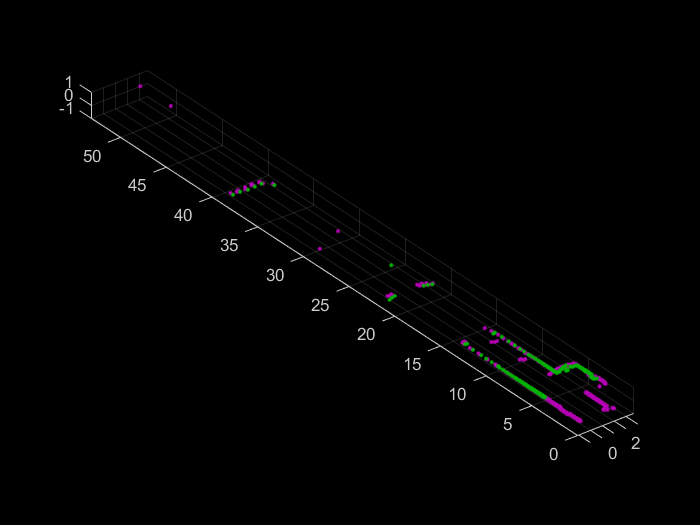

     5



ans =     0.9981    0.0619         0         0
   -0.0619    0.9981         0         0
         0         0    1.0000         0
    0.3186    4.9813         0    1.0000


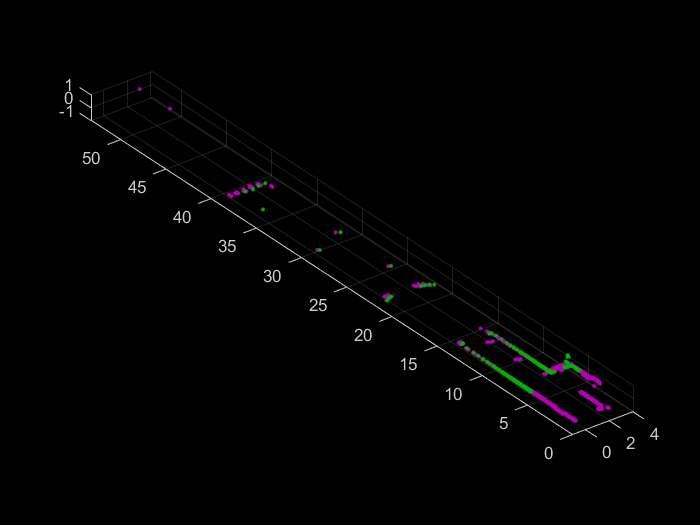

     6



ans =     0.9982    0.0598         0         0
   -0.0598    0.9982         0         0
         0         0    1.0000         0
    0.2805    5.8630         0    1.0000


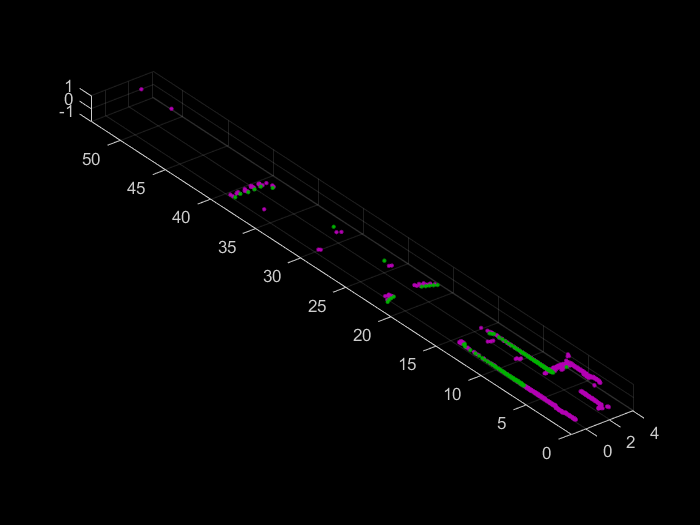

     7



ans =     1.0000   -0.0054         0         0
    0.0054    1.0000         0         0
         0         0    1.0000         0
    0.1351    6.6340         0    1.0000


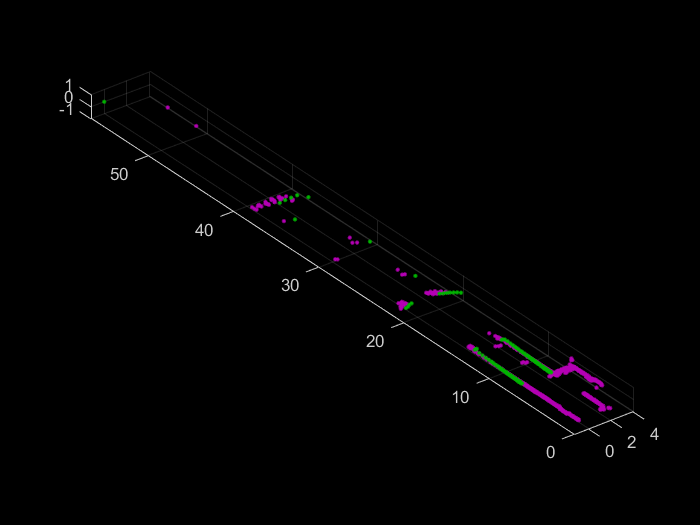

     8



ans =     0.9980   -0.0639         0         0
    0.0639    0.9980         0         0
         0         0    1.0000         0
    0.1654    7.9429         0    1.0000


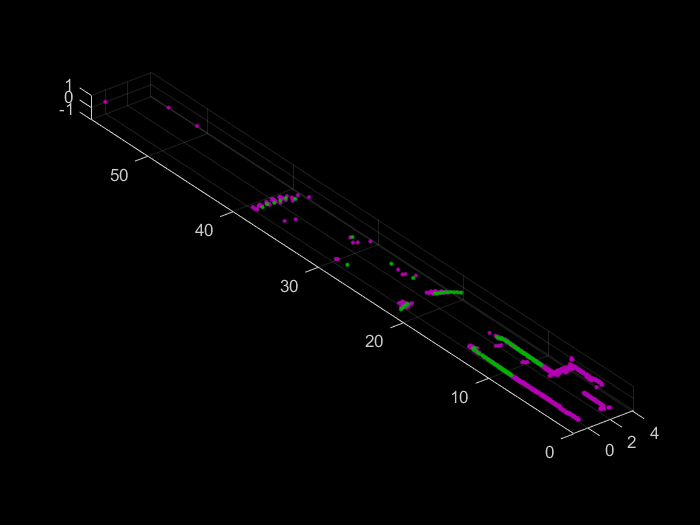

     9



ans =     0.9981   -0.0612         0         0
    0.0612    0.9981         0         0
         0         0    1.0000         0
    0.1656    8.8733         0    1.0000


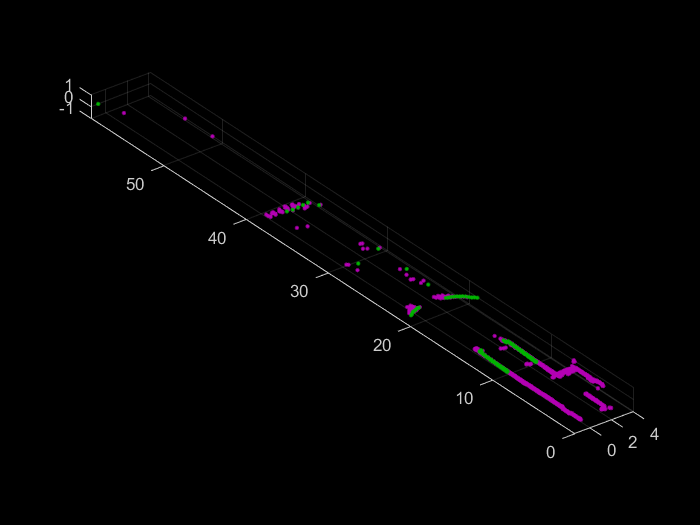

clear;clc;close all

laser_map = pcread('0.ply');

tform_init = affine3d([1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]);

robot_tf=cell(1,10);
robot_tf{1} = tform_init;

for i = 1:1:9
    
    disp(i);
    
    % read
    str = [num2str(i) , '.ply'];  
    curr_ply = pcread(str);

    % icp
    [tform_init, curr_ply] = pcregistericp(curr_ply, laser_map, 'Metric','pointToPoint', 'InitialTransform', tform_init, 'MaxIterations', 100, 'Tolerance', [0.01, 0.001]);
    %[tform_init, curr_ply] = myicp_ransac_plus(curr_ply, laser_map,"PointToLine","kdtree");
    %[tform_init,curr_ply] = my_ransac_icp(curr_ply, laser_map,"relative");
    tform_init.T
    robot_tf{i+1} = tform_init;
    figure;
    pcshowpair(laser_map, curr_ply, 'MarkerSize', 50);
    % merge
    
    laser_map = pcmerge(laser_map, curr_ply, 0.01);
   
end

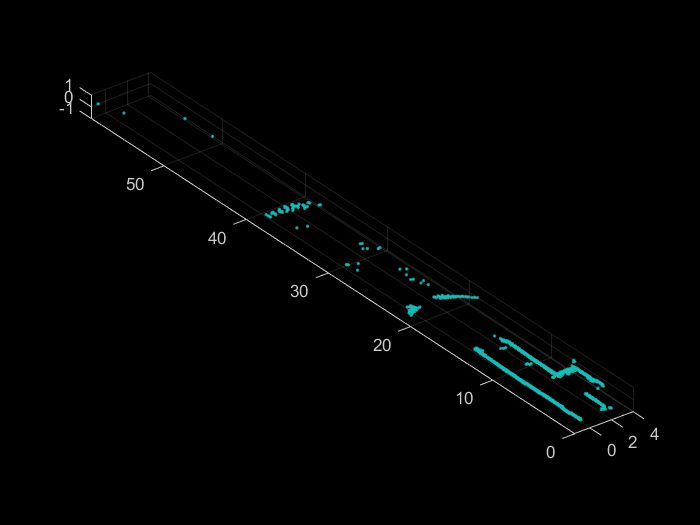


figure;
pcshow(laser_map, 'MarkerSize', 20);

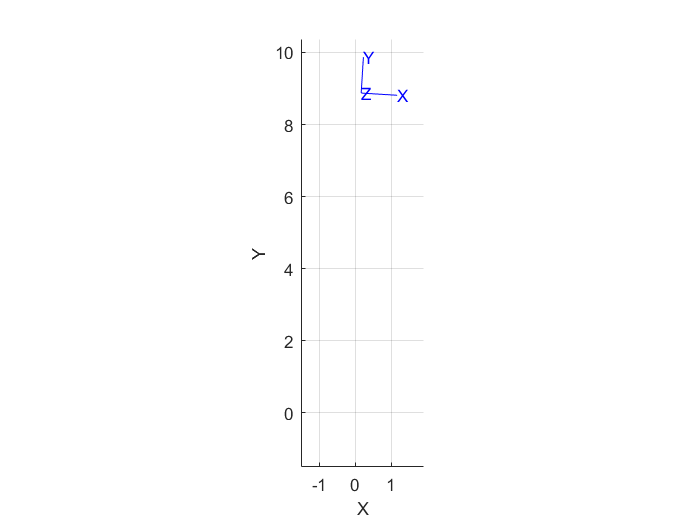


Tx1=robot_tf{1,1}.T';
for i=2:10
    Tx1 = cat(3,Tx1,robot_tf{1,i}.T');
end
figure
tranimate(Tx1)

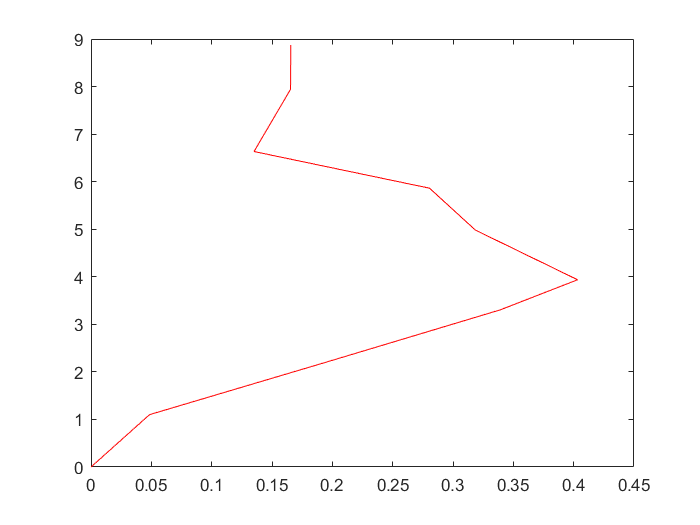

%生成gif
%tranimate(Tx1,'movie','quat.gif');
% figure
% plot(transl(Tx1));
% figure
% plot(tr2rpy(Tx1));

tran1=transl(Tx1);
tr1=tr2rpy(Tx1);
tr1=tr1(:,3);
figure
plot(tran1(:,1),tran1(:,2),"r");

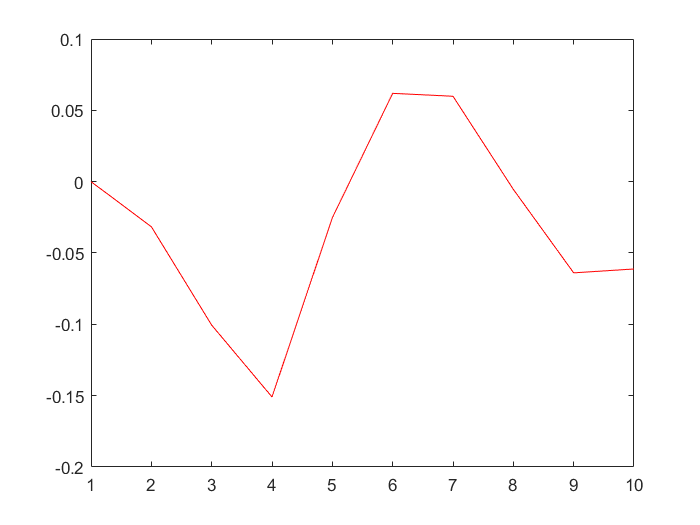

figure
plot(tr1,"r");